### Load scatter data set

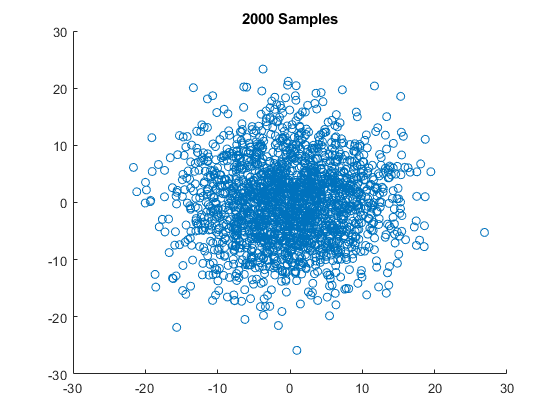

samples_2000 = readmatrix('../data/scatter_samples_2000.csv');
samples_2000 = samples_2000(2:length(samples_2000),2:3);
samples_20 = readmatrix('../data/scatter_samples_20.csv');
samples_20 = samples_20(2:length(samples_20),2:3);
scatter(samples_2000(:,1),samples_2000(:,2))
title("2000 Samples")

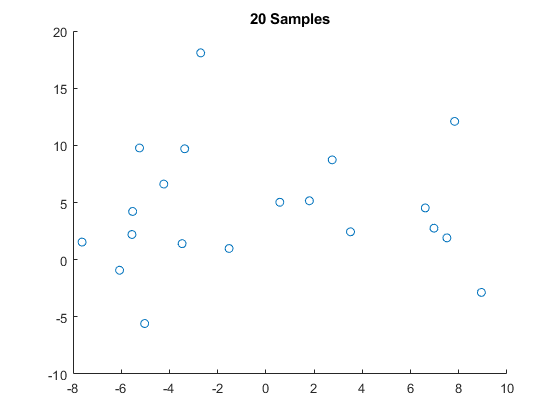

scatter(samples_20(:,1),samples_20(:,2))
title("20 Samples")

### Running KMeans on both sampling sets two times and visualising clusters

First on data set with 2000 points.

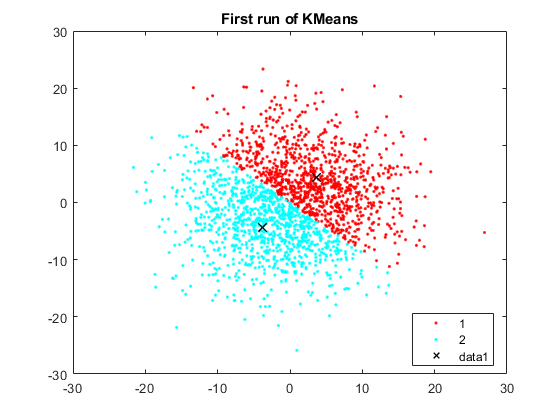

[labels_1,centroids_1] = kmeans(samples_2000,2);
[labels_2,centroids_2] = kmeans(samples_2000,2);
gscatter(samples_2000(:,1),samples_2000(:,2),labels_1)
title("First run of KMeans")
hold on
scatter(centroids_1(:,1),centroids_1(:,2),80,'black','x',"LineWidth",1)
hold off

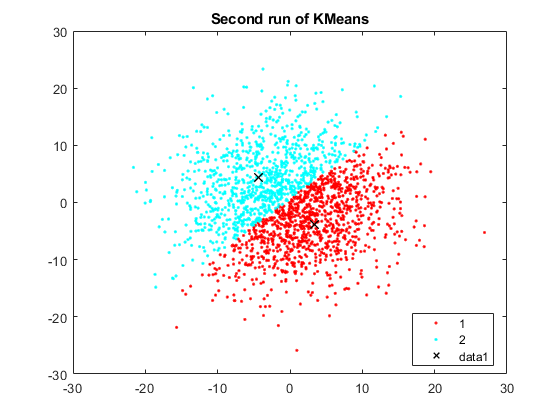

gscatter(samples_2000(:,1),samples_2000(:,2),labels_2)
title("Second run of KMeans")
hold on
scatter(centroids_2(:,1),centroids_2(:,2),80,'black','x',"LineWidth",1)
hold off

Now on data set with just 20 points.

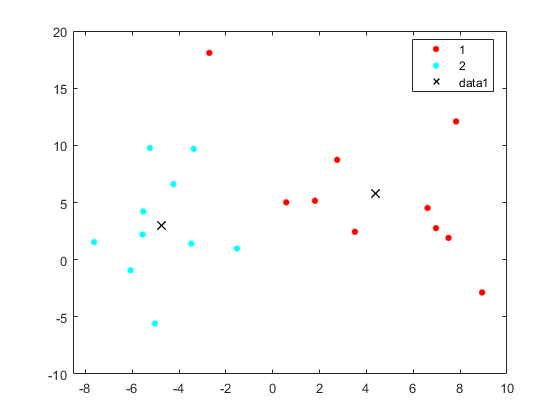

[labels_1,centroids_1] = kmeans(samples_20,2);
[labels_2,centroids_2] = kmeans(samples_20,2);

gscatter(samples_20(:,1),samples_20(:,2),labels_1)
hold on
scatter(centroids_1(:,1),centroids_1(:,2),80,'black','x',"LineWidth",1)
hold off

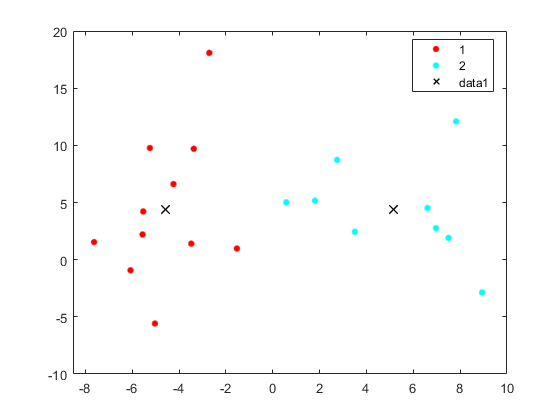

gscatter(samples_20(:,1),samples_20(:,2),labels_2)
hold on
scatter(centroids_2(:,1),centroids_2(:,2),80,'black','x',"LineWidth",1)
hold off